## Coded by Author ZW Du in Austin on April 30, 2020

Copyright: This code file is licensed under a CC-BY-NC-SA 4.0

Now only shared to Michael and Petter without any limitation.

## Guideline

[https://petterhol.me/2018/02/07/fastest-network-sir-code-in-the-east/](https://petterhol.me/2018/02/07/fastest-network-sir-code-in-the-east/) Fastest network-SIR code in the East By Petter, Update July 30, 2018

- initialize all nodes to susceptible 

- get a random source node i 

- insert the infection event of i (at time zero) into the heap 

- while the heap is not empty: 

-     i := root of heap (the smallest element) 

-     if i is infected: 

-         mark i as recovered 

-         move the last element of the heap to the root 

-         heapify-down from the root 

-     else: [1] 

-         mark i infected 

-         add an exponential random number to i?s event time 

-         heapify-down from i 

-         for susceptible neighbors j of i: 

-             get a candidate infection time t (exponentially distributed + current time) 

-             if t is earlier than i?s recovery time and j?s current infection time: 

-                 if j is not on the heap: 

-                     add it to the end of the heap 

-                     update the infection time and heapify-up from j [2] 

- Comments: 

- [1] i has to be susceptible here, it can?t be in the recovered state 

- [2] since this update can only make j?s next event time earlier, we can use heapify-up 

- * heapify-down for cases when a parent-event might be happen later than its children 

## Reproducity

rng(100)

## Read network file

% Network files have 5 columns: FROM TO GR1 GR2 weight
AustinSmall10Net10 = readNetFile('pholme_sir/AustinSmall10Net10.csv');

Uni_Nodes = unique([AustinSmall10Net10{:,1}; AustinSmall10Net10{:,2}]);
len_Nodes = length(Uni_Nodes);

% Get neighbor list
neighs = cell(len_Nodes, 1);
for i=1:len_Nodes
    neighs{i} = AustinSmall10Net10{find(AustinSmall10Net10{:,1} == Uni_Nodes(i)),2};
end

## Read viral dynamic file

% log(V(t)) in Hour scale postinfection
ViralD = readViralFile('pholme_sir/Withinhost simulation.csv');

% cumulative probability of log(V(t))
ViralP = ViralD{:,3};

## Initialize parameters

initialize_Model;

% Key scaling factor of transmission rate, which should calibrate to real
% data
alpha = 10;

## Network transmission

- If node i is infected:

-     for susceptible neighbors j of i:

-         get a candidate infection time t (event distributed + current time).  The event distributed time can be: $-log(RAND) =  \alpha \cdot   \frac{  \sum_{t=1}^\tau log(V(\Delta t)))) } {\sum_{t=1}^\inf  log(V(\Delta t))))}$

t = 1;
IT = [];
% while the heap is not empty:
while heap.nq>0 || t==1
    % Infection of first time to deal
    infectors = find(I==1 & RecT==RecT_Max);
    
    % for infected i:
    for i = 1:length(infectors)
        infector = infectors(i);
        
        % Update i's recovery time if not assigned
        if RecT(infector) == RecT_Max
            step = t - log(rand)/rateIR;
            heap.nq = heap.nq+1;
            heap.queue(heap.nq,:) = [infector, I_lab, R_lab, step];
            RecT(infector) = step;
        end
        
        % for susceptible neighbors j of i:
        temp_neig = neighs{infector};
        for j = 1:length(temp_neig)
            temp_neig_j = temp_neig(j);
            if S(temp_neig_j)==1
                ini_Node = temp_neig_j;
                
                % if j is not on the heap:
                if length(find(heap.queue(:,1)==ini_Node))==0
                    
                    temp = find(ViralP>= -log(rand)/alpha, 1);
                    if length(temp)==0
                        step = NEVER; % a large value to denote the impossible.
                    else
                        step = t + temp/24; % ViralP is in hourly scale
                    end
                    % % Prior without withinhost
                    % step = t - log(rand)/rateSI;
                    % if t is earlier than i?s recovery time:
                    if  step<=RecT(infector) & step~=NEVER
                        heap.nq = heap.nq+1;
                        heap.queue(heap.nq,:) = [ini_Node, S_lab, I_lab, step];
                    end
                end
            end
        end
        
    end
    
    % Order by event time to keep descending order
    [a, b] = sort(heap.queue(:,end), 'descend');
    heap.queue = heap.queue(b, :);
    
    % Update queue at time t
    Event_t = 0;
    sum_newI = 0;
    if heap.nq>0
        
        % ZW: @ALL, not sure whether to increase time t with step 0.1 is good choice
        t = t+0.1;
        Event_t = t;
        while Event_t<=t && heap.nq>0
            temp = heap.queue(heap.nq, :);
            N_id = temp(1); From = temp(2); ToTo = temp(3); Event_t = temp(4);
            if Event_t<=t;
                eval( ['Flag_First =', Labs_Str{ismember(Labs, From)}, '(N_id);'] );
                if Flag_First==1 % To check whether it has ever dealer
                    if ToTo==I_lab
                        sum_newI = sum_newI+1;
                    end
                    eval( [Labs_Str{ismember(Labs, From)}, '(N_id) = 0;'] );
                    eval( [Labs_Str{ismember(Labs, ToTo)}, '(N_id) = 1;'] );
                end
                heap.queue(heap.nq, :) = [];
                heap.nq = heap.nq-1;
            end
        end
        IT = [IT; t sum_newI];
    end
end

## Plot for newly incidence

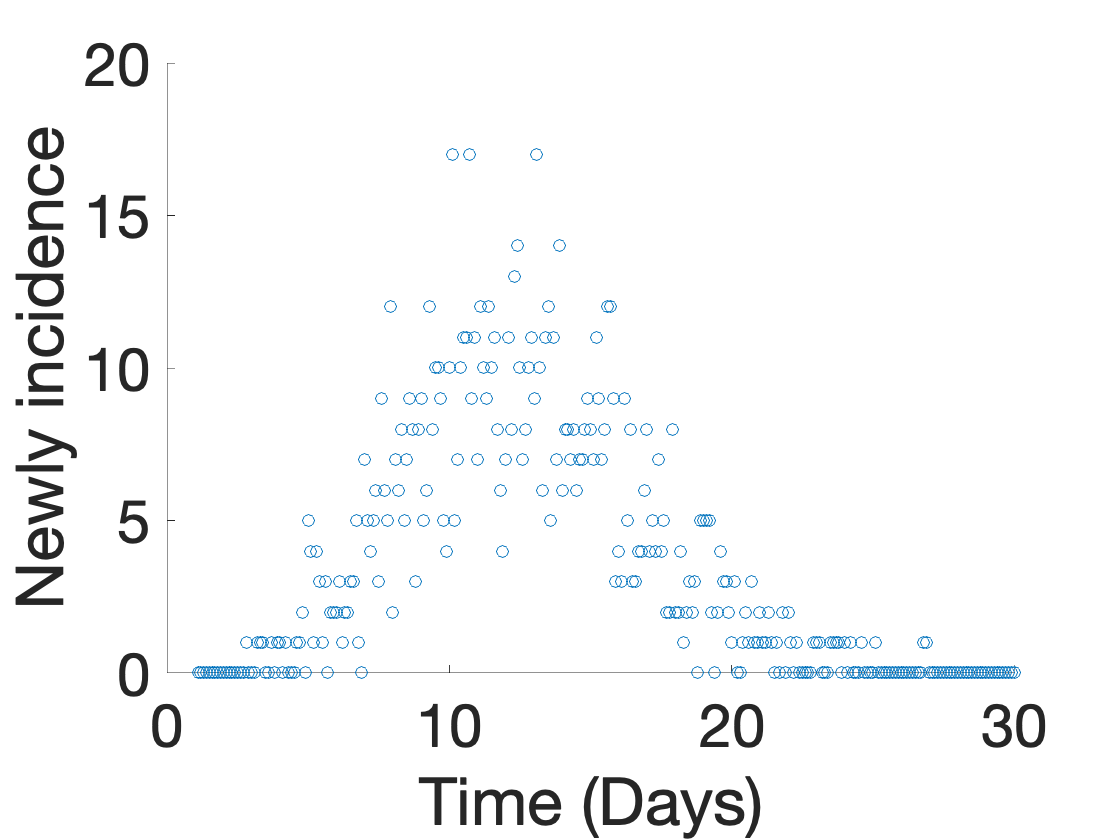

scatter(IT(:,1),IT(:,2));
xlabel('Time (Days)')
ylabel('Newly incidence')
set(gca, 'fontsize', 30)
xlim([0, 30])